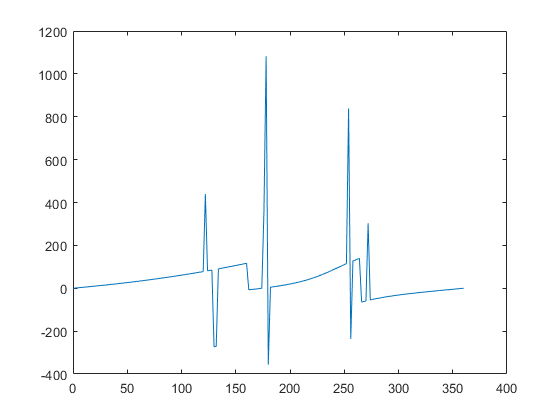

clear
syms t real
syms theta rho sigma phi delta real % initial angles, phi is fixed ground link angle
syms beta(t) alpha(t) gamma(t)  % time step angles
syms W1(beta) V1(alpha) U1(gamma) G1 % Vectors
syms W V U G real % magnitudes

% Define All Vectors
W1 = W*exp(i*(beta+theta));
V1 = V*exp(i*(alpha+rho));
U1 = U*exp(i*(gamma+sigma));
G1 = G*exp(i*(phi));

% Vector Loop Equation for mechanism one and two
LoopPositionOne = W1 + V1 - U1 - G1;
LoopPositionTwo = G1 + U1 - V1 - W1;

% For the four bar mechanism (not including arbitrary extra link L_1), there is 11 variables.
% 4 lengths per link
% 4 inital angles per link
% 3 rotating angles per non-grounded links

% Fsolve can be used to solve for any two varibles, e.g. angle  angle, angle length, ect.
% You just need to supply 9 out of ll varibles.

% I will subsitute 9 variables; 4 lengths, 4 intial angles, and beta driven angle...
% fsolve() will be used to determine the remaining two rotating angles.
% Mechanism One
subsitutionVariables = [W V U G theta rho sigma phi];    % Eight constant variables
subsitutionValues = [1.75 2 2 sqrt(.866^2 + 0.5^2)...
    90 -16.0139 58.1173 atan2d(-0.5, 0.866)];             % Eight subsitution values
subsitutionValues(5:8) = subsitutionValues(5:8)*pi/180;  % Conversion to radians for complex form

LoopPositionOneInitial = subs(LoopPositionOne, subsitutionVariables, subsitutionValues);
Angles = []; % [Beta, Alpha, Gamma]
BetaAngles = (0:2:360)*pi/180;
options = optimset('Algorithm', 'levenberg-marquardt','Display','off');

for i = 1:length(BetaAngles)  
    f = subs(LoopPositionOneInitial, beta, BetaAngles(i)); % Subsitute driving angle
    % Next line splits symbolic expression into real and imaginery parts, and turns  multivarible argument into
    % a linear vector argument. This is a requirment, as fsolve will implicity solve for complex solutions if
    % the passed function(s) ever returns complex outputs. :(
    f = matlabFunction([real(f), imag(f)], 'Vars',{[alpha, gamma]});
    Angles(i,1) = BetaAngles(i);
    Angles(i,2:3) = fsolve(f, [0 0], options);
end

for  i = 1:10
    KinematicChain = [];
    KinematicChain(1) = subs(W1,[W,beta,theta],[])
end
Angles = Angles*180/pi;
Beta = Angles(:,1);
Alpha = Angles(:,2);
Gamma = Angles(:,3);
plot(Beta, Alpha);